### Defining Input Values

%Input values chosen by user
t1 = 0:0.01:3.0; %accelerated climb phase duration
t2 = 3.0:0.01:6; %microgravity phase duration
t3 = 6:0.01:10; %recovery phase duration
a1 = 4.9; %accelerated climb phase acceleration
a2 = -9.8; %microgravity phase acceleration
a3 = 1.1; %recovery phase acceleration
v_initial = 0; %initial velocity
h_final = 10; %final altitude
h_initial = 0; % initial altitude

### Acceleration vs. Time Plot

The results from the Unity simulation can be plotted on the same graph as the desired acceleration. This is done by implementing a moving average for the acceleration output data.

%Results of acceleration 
% %Moving average
% data1 = AccY;
% windowSize = 320;
% n = length(data1);
% movingAverage_1 = zeros(1, n);
% 
% for i = 1:n
%     % Define the window range
%     startIdx = max(1, i - floor(windowSize / 2));
%     endIdx = min(n, i + floor(windowSize / 2));
% 
%     % Compute the average
%     movingAverage_1(i) = mean(data1(startIdx:endIdx));
% end
% 
% windowSize = 320;
% n = length(Time1);
% movingAverage_Time = zeros(1, n);
% 
% for i = 1:n
%     % Define the window range
%     startIdx = max(1, i - floor(windowSize / 2));
%     endIdx = min(n, i + floor(windowSize / 2));
% 
%     % Compute the average
%     movingAverage_Time(i) = mean(Time1(startIdx:endIdx));
% end
% 
% %plotting the results
% plot(movingAverage_Time(:,1:2700), movingAverage_1(:,1:2700),'k');
% hold on;

The section above can be commented out when results are not to be plotted. The legend in the section of code below should be commented out and the hold on function should be added in. The desired acceleration plots are calculated using only the input variables as defined by the user.

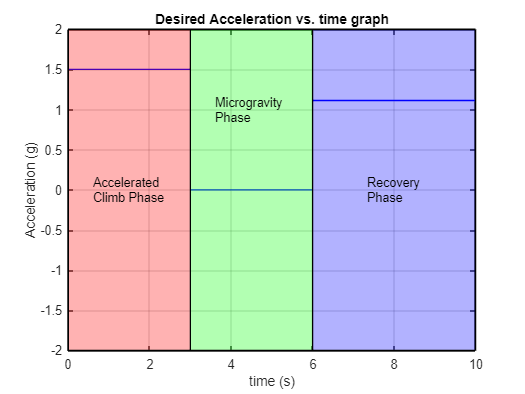

%plotting the accelerations
plot(t1,((a1+9.8)/9.8)*ones(1,length(t1)),'b');
hold on;
xlabel('time (s)');
ylabel('Acceleration (g)')
title('Desired Acceleration vs. time graph')
grid on;
plot(t2,((a2+9.8)/9.8)*ones(1,length(t2)),'b');
plot(t3,((a3+9.8)/9.8)*ones(1,length(t3)),'b');

%Marking different phases of flight

x1 = [0 t1(1,length(t1)) t1(1,length(t1)) 0];
y1 = [-2 -2 2 2];
patch(x1,y1,'r','FaceAlpha',0.3)
str = {'Accelerated','Climb Phase'};
text(0.2*t1(1,length(t1)),0,str)

x2 = [t1(1,length(t1)) t2(1,length(t2)) t2(1,length(t2)) t1(1,length(t1))];
y2 = [-2 -2 2 2];
patch(x2,y2,'g','FaceAlpha',0.3)
str = {'Microgravity','Phase'};
text(0.6*t2(1,length(t2)),1,str)

x3 = [t2(1,length(t2)) t3(1,length(t3)) t3(1,length(t3)) t2(1,length(t2))];
y3 = [-2 -2 2 2];
patch(x3,y3,'b','FaceAlpha',0.3)
str = {'Recovery','Phase'};
text(22/30*t3(1,length(t3)),0,str)

%legend('UAV actual acceleration','Desired acceleration');
hold off;

### Velocity vs. Time Plot

The results from the Unity simulation, i.e., measured velocities, can be plotted on the same graph as the desired output if needed. Else the section of code below can be commented.

%Plotting results
% plot(Time1(1:2980,:), VelocityY(1:2980,:), 'b');
% hold on;

The desired velocities are calculated as the integrals of the acceleration functions in terms of time. The equations for this are as follows:


$$v = \int a \cdot dt = a \cdot t + C$$


For the accelerated climb phase, $t \in t_1$ and at $t = 0$, $v = v_{initial}
$.


$$\Rightarrow v = a_1 \cdot t + v_{initial}$$


For the microgravity phase, $t \in t_2$ and the velocity at the start of the phase is equal to the velocity at the end of the accelerated climb phase.


$$v = t \cdot a_2 + v_{ac,end}-a_2 \cdot t_{ac,end}$$


For the recovery phase, t \in t_3 and the velocity at the start of the phase is equal to the velocity at the end of the microgravity phase.


$$v = t \cdot a_3 + v_{mg,end}-a_3 \cdot t_{mg,end}$$


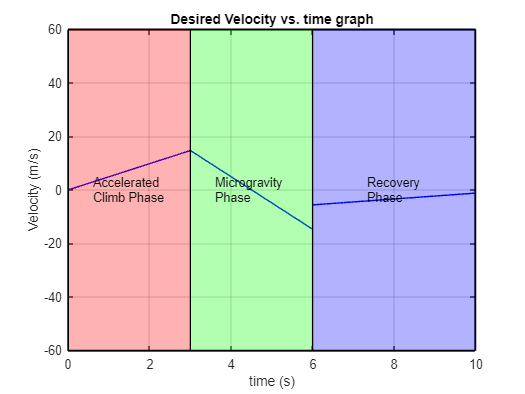

%plotting the velocities
v1 = t1*a1 + v_initial;
v_max = v1(1,end);
v2 = t2*a2+v_max-a2*t1(1,end);

s1=(a1/2)*t1.^2+v_initial*t1+h_initial;
s2=(a2/2)*t2.^2+(v_max-a2*t1(1,end))*t2+s1(1,end)-(a2/2)*(t1(1,end))^2-(v_max-a2*t1(1,end))*t1(1,end);
%s3=(a3/2)*t3.^2+(v2(1,end)-a3*t2(1,end))*t3+h_final-(a3/2)*(t3(1,end))^2-(v2(1,end)-a3*t2(1,end))*t3(1,end);

v3 = (t3*a3)+(((h_final-s2(1,end)))/t3(1,end))-(t3(1,end)*a3);
plot(t1,v1,'b');
hold on;
xlabel('time (s)');
ylabel('Velocity (m/s)')
title('Desired Velocity vs. time graph')
grid on;
plot(t2,v2,'b');
plot(t3,v3,'b');

%Marking different phases of flight

x1 = [0 t1(1,length(t1)) t1(1,length(t1)) 0];
y1 = [-60 -60 60 60];
patch(x1,y1,'r','FaceAlpha',0.3)
str = {'Accelerated','Climb Phase'};
text(0.2*t1(1,length(t1)),0,str)

x2 = [t1(1,length(t1)) t2(1,length(t2)) t2(1,length(t2)) t1(1,length(t1))];
y2 = [-60 -60 60 60];
patch(x2,y2,'g','FaceAlpha',0.3)
str = {'Microgravity','Phase'};
text(0.6*t2(1,length(t2)),0,str)

x3 = [t2(1,length(t2)) t3(1,length(t3)) t3(1,length(t3)) t2(1,length(t2))];
y3 = [-60 -60 60 60];
patch(x3,y3,'b','FaceAlpha',0.3)
str = {'Recovery','Phase'};
text(22/30*t3(1,length(t3)),0,str)

%legend('UAV actual velocity','Desired velocity');
hold off;

### Altitude vs. Time Plot

The results from the Unity simulation, i.e., measured altitude, can be plotted on the same graph as the desired output if needed. Else the section of code below can be commented.

% %Plotting results
% plot(Time1(1:2980,:), PositionY1(1:2980,:),'r');
% hold on;

The desired displacements are calculated as second integrals of acceleration as a function of time. The equations for this are as follows:


$$s = \int\int a \cdot dt = \int (a \cdot t + C) \cdot dt = \frac{a}{2} \cdot t^2 + C \cdot t + C_1$$


For the accelerated climb phase, $t \in t_1$. At $t = 0$, $s = h_{initial}
$ and $C = v_{initial}$ as shown in the velocity vs. time section earlier.


$$s = \frac{a_1}{2}t^2+ v_{initial} \cdot t + h_{initial}
$$


For the microgravity phase, $t \in t_2
$. At the beginning of this phase the altitude is the same as the altitude at the end of the accelerated climb phase and $C = v_{ac,end}-a_2 \cdot t_{ac,end}$ as shown in the velocity vs. time section earlier.


$$s = \frac{a_2}{2}t^2+ (v_{ac,end} - a_2 \cdot t_{ac,end}) \cdot t + (s_{ac,end}-\frac{a_2}{2}\cdot t_{ac,end}^2 - (v_{ac,end} - a_2 \cdot t_{ac,end}) \cdot t_{ac,end})$$


For the recovery phase, $t \in t_3

$. At the end of this phase, the altitude is equal to the final altitude chosen by the user and $C = v_{mg,end}-a_3 \cdot t_{mg,end}$ as shown in the velocity vs. time section earlier.


$$s = \frac{a_3}{2}t^2 + (v_{mg,end} - a_3 \cdot t_{mg,end})\cdot t + (h_{final} - \frac{a_3}{2}\cdot t_{r,end}^2) - (v_{mg,end} - a_3 \cdot t_{mg,end})\cdot t_{r,end}$$


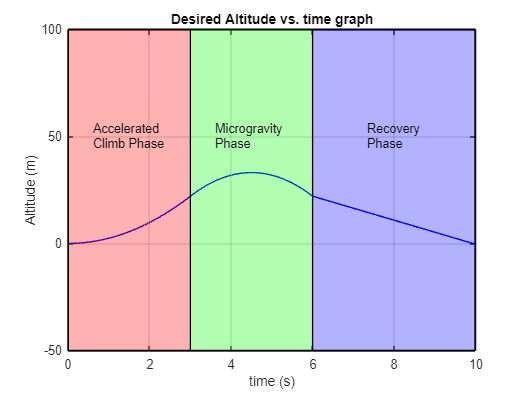

%plotting the displacements
s3 = v3(1,1)*(t3-t3(1,1)) + s2(1,end);

plot(t1,s1,'b');
hold on;
xlabel('time (s)');
ylabel('Altitude (m)')
title('Desired Altitude vs. time graph')
grid on;
plot(t2,s2,'b');
plot(t3,s3,'b');

x1 = [0 t1(1,length(t1)) t1(1,length(t1)) 0];
y1 = [-50 -50 100 100];
patch(x1,y1,'r','FaceAlpha',0.3)
str = {'Accelerated','Climb Phase'};
text(0.2*t1(1,length(t1)),50,str)

x2 = [t1(1,length(t1)) t2(1,length(t2)) t2(1,length(t2)) t1(1,length(t1))];
y2 = [-50 -50 100 100];
patch(x2,y2,'g','FaceAlpha',0.3)
str = {'Microgravity','Phase'};
text(0.6*t2(1,length(t2)),50,str)

x3 = [t2(1,length(t2)) t3(1,length(t3)) t3(1,length(t3)) t2(1,length(t2))];
y3 = [-50 -50 100 100];
patch(x3,y3,'b','FaceAlpha',0.3)
str = {'Recovery','Phase'};
text(22/30*t3(1,length(t3)),50,str)

%legend('UAV actual altitude','Desired altitude')
hold off;

### Outputs for csv file to provide input locations for Unity simulation

%creating a list of times and altitudes to put in csv file for Unity
%concatenate all the time and altitude arrays 
% transpose into a column vector
Times_output = cat(2,t1,t2,t3);
Times_output = Times_output.';
Altitude_output = cat(2,s1,s2,s3);
Altitude_output = Altitude_output.';